# Ejemplo de bucle de entrenamiento propio

Se va a entrenear una red neuronal convolucional que clasifica digitos del 0 al 9.

Por tanto tenemos 10 clases. Se va hacer un bucle de entrenamiento propio, para que se pueda comprender como se hace un lazo concreto.

## Preparación de datos

Extrae los datos de un fichero . zip, y nos construye un arbol de directorios.

Este arbol contiene ejemplos de imagenes de 28x28x1, y en cada carpeta se tienen los ejemplos de cada digito.

unzip("DigitsData.zip")

imds = imageDatastore("DigitsData", ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

Se construyen dos datastores uno para entrenamiento y otro para validación.

El segundo deve contener el %10 de los datos.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.9,"randomize");
inputSize = [28 28 1];
pixelRange = [-5 5];

imageAugmenter = imageDataAugmenter( ...
    RandXTranslation=pixelRange, ...
    RandYTranslation=pixelRange);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,DataAugmentation=imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Para poder crear la red CNN, se deve de saber el numero de clases

classes = categories(imdsTrain.Labels);
numClasses = numel(classes);

## Definición de la arquitectura de la red CNN

layers = [
    imageInputLayer(inputSize,Normalization="none")
    convolution2dLayer(5,20,Padding="same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,20,Padding="same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,20,Padding="same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];
net = dlnetwork(layers)

net =   dlnetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
    Connections: [11×2 table]
     Learnables: [14×3 table]
          State: [6×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


## Definición del bucle de entrenamiento

El numero de epocas(Pasar todos los minibaches que tenemos, todos los patrones han pasado por las red minimo una vez) y el tamaño del minibatch.

numEpochs = 10;
miniBatchSize = 128;

Specify the options for SGDM optimization. Specify an initial learn rate of 0.01 with a decay of 0.01, and momentum 0.9.

initialLearnRate = 0.01;
decay = 0.01;
momentum = 0.9;

## Entrenamiento de modelo

Create a [`minibatchqueue`](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) object that processes and manages mini-batches of images during training. For each mini-batch:

- Use the custom mini-batch preprocessing function `preprocessMiniBatch` (defined at the end of this example) to convert the labels to one-hot encoded variables.

- Format the image data with the dimension labels `"SSCB"` (spatial, spatial, channel, batch). By default, the `minibatchqueue` object converts the data to `dlarray` objects with underlying type `single`. Do not format the class labels.

- Discard partial mini-batches.

- Train on a GPU if one is available. By default, the `minibatchqueue` object converts each output to a `gpuArray` if a GPU is available. Using a GPU requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

mbq = minibatchqueue(augimdsTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""], ...
    PartialMiniBatch="discard");

Initialize the velocity parameter for the SGDM solver.

velocity = [];

Calculate the total number of iterations for the training progress monitor.

numObservationsTrain = numel(imdsTrain.Files);
numIterationsPerEpoch = floor(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

Initialize the `TrainingProgressMonitor` object. Because the timer starts when you create the monitor object, make sure that you create the object close to the training loop.

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info=["Epoch" "LearnRate"], ...
    XLabel="Iteration");

Train the network using a custom training loop. For each epoch, shuffle the data and loop over mini-batches of data. For each mini-batch:

- Evaluate the model loss, gradients, and state using the `dlfeval` and `modelLoss` functions and update the network state.

- Determine the learning rate for the time-based decay learning rate schedule.

- Update the network parameters using the `sgdmupdate` function.

- Update the loss, learn rate, and epoch values in the training progress monitor.

- Stop if the Stop property is true. The Stop property value of the `TrainingProgressMonitor` object changes to true when you click the Stop button.

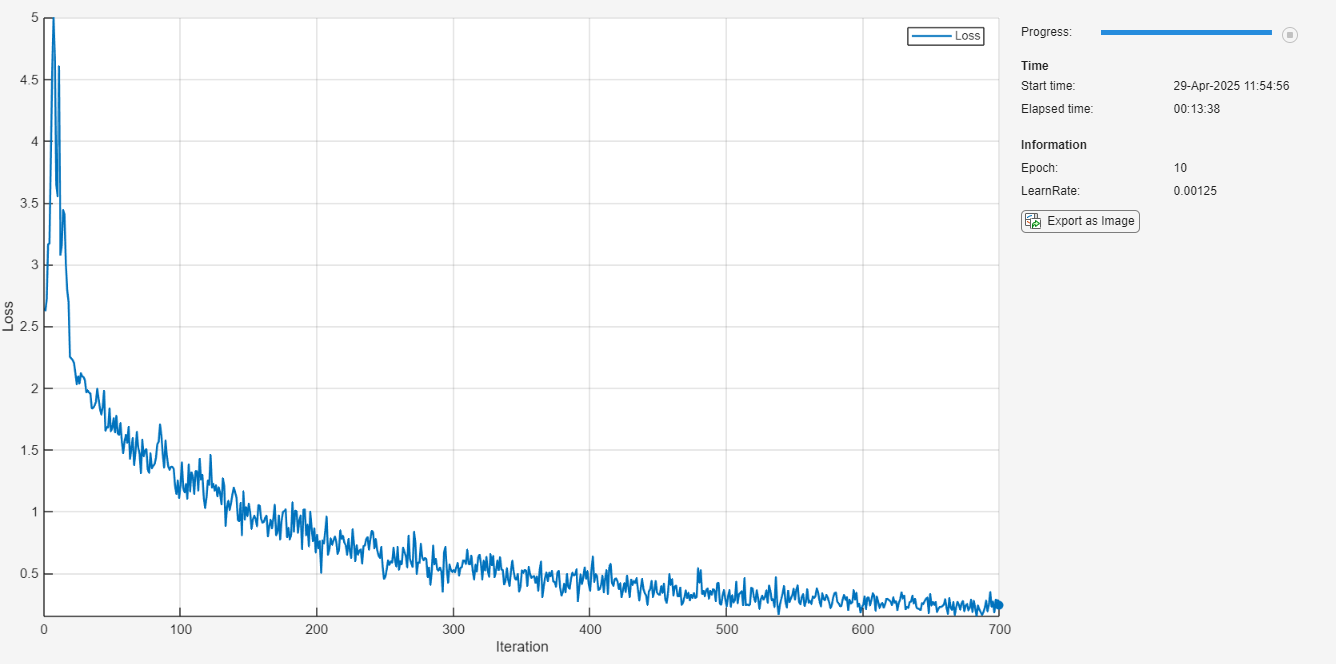

epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop

        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [X,T] = next(mbq);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        [loss,gradients,state] = dlfeval(@modelLoss,net,X,T);
        net.State = state;
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);
        
        % Update the network parameters using the SGDM optimizer.
        [net,velocity] = sgdmupdate(net,gradients,velocity,learnRate,momentum);
        
        % Update the training progress monitor.
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch,LearnRate=learnRate);
        monitor.Progress = 100 * iteration/numIterations;
    end
end

## Test Model

Test the classification accuracy of the model by comparing the predictions on the validation set with the true labels.

After training, making predictions on new data does not require the labels. Create `minibatchqueue` object containing only the predictors of the test data:

- To ignore the labels for testing, set the number of outputs of the mini-batch queue to 1.

- Specify the same mini-batch size used for training.

- Preprocess the predictors using the `preprocessMiniBatchPredictors` function, listed at the end of the example.

- For the single output of the datastore, specify the mini-batch format `"SSCB"` (spatial, spatial, channel, batch).

numOutputs = 1;

mbqTest = minibatchqueue(augimdsValidation,numOutputs, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatchPredictors, ...
    MiniBatchFormat="SSCB");

Loop over the mini-batches and classify the images using `modelPredictions` function, listed at the end of the example.

YTest = modelPredictions(net,mbqTest,classes);

Evaluate the classification accuracy.

TTest = imdsValidation.Labels;
accuracy = mean(TTest == YTest)

accuracy = 0.9550

Visualize the predictions in a confusion chart.

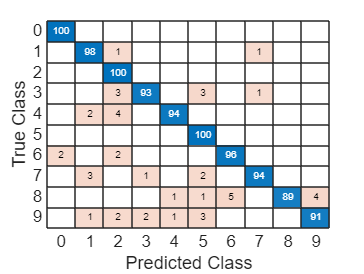

figure
confusionchart(TTest,YTest)

Large values on the diagonal indicate accurate predictions for the corresponding class. Large values on the off-diagonal indicate strong confusion between the corresponding classes.

## Supporting Functions

### Model Loss Function

The `modelLoss` function takes a `dlnetwork` object `net`, a mini-batch of input data `X` with corresponding targets `T` and returns the loss, the gradients of the loss with respect to the learnable parameters in `net`, and the network state. To compute the gradients automatically, use the `dlgradient` function.

function [loss,gradients,state] = modelLoss(net,X,T)

% Forward data through network.
[Y,state] = forward(net,X);

% Calculate cross-entropy loss.
loss = crossentropy(Y,T);

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

### Model Predictions Function

The `modelPredictions` function takes a `dlnetwork` object `net`, a `minibatchqueue` of input data `mbq`, and the network classes, and computes the model predictions by iterating over all data in the `minibatchqueue` object. The function uses the `onehotdecode` function to find the predicted class with the highest score.

function Y = modelPredictions(net,mbq,classes)

Y = [];

% Loop over mini-batches.
while hasdata(mbq)
    X = next(mbq);

    % Make prediction.
    scores = predict(net,X);

    % Decode labels and append to output.
    labels = onehotdecode(scores,classes,1)';
    Y = [Y; labels];
end

end

### Mini Batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors and labels using the following steps:

- Preprocess the images using the `preprocessMiniBatchPredictors` function.

- Extract the label data from the incoming cell array and concatenate into a categorical array along the second dimension.

- One-hot encode the categorical labels into numeric arrays. Encoding into the first dimension produces an encoded array that matches the shape of the network output.

function [X,T] = preprocessMiniBatch(dataX,dataT)

% Preprocess predictors.
X = preprocessMiniBatchPredictors(dataX);

% Extract label data from cell and concatenate.
T = cat(2,dataT{1:end});

% One-hot encode labels.
T = onehotencode(T,1);

end

### Mini-Batch Predictors Preprocessing Function

The `preprocessMiniBatchPredictors` function preprocesses a mini-batch of predictors by extracting the image data from the input cell array and concatenate into a numeric array. For grayscale input, concatenating over the fourth dimension adds a third dimension to each image, to use as a singleton channel dimension.

function X = preprocessMiniBatchPredictors(dataX)

% Concatenate.
X = cat(4,dataX{1:end});

end

*Copyright 2019-2023 The MathWorks, Inc.*